panel = irdata_141630(3, 2).ImpulseResponse; % change with new ir_data
source = irdata_141630(2, 2).ImpulseResponse; % change with new ir_data

panel_ir = panel.Amplitude;
source_ir = source.Amplitude;

% findpeaks(panel_ir)
% findpeaks(source_ir)
[panel_max, panel_idx] = max(abs(panel_ir))

panel_max = 0.0714

panel_idx = 3317

[source_max, source_idx] = max(abs(source_ir))

source_max = 0.0282

source_idx = 3382

shift = source_idx - panel_idx

shift = 65

scale = panel_max / source_max

scale = 2.5335

panel_ir_norm = panel_ir / panel_max;
source_ir_norm = source_ir / source_max;

[y, fs] = audioread("arthur_clip_48k.wav");

source_scale = 2;
panel_scale = source_scale / scale

panel_scale = 0.7894

y_panel = [zeros(shift, 1); -panel_scale * y];
y_source = [source_scale * y; zeros(shift, 1)];

lamda = .1; % tune experimentally

H = fft(panel_ir_norm);
H_conj = conj(H);
G = H_conj ./ (H .* H_conj + lamda);
panel_inverse_ir = ifft(G);

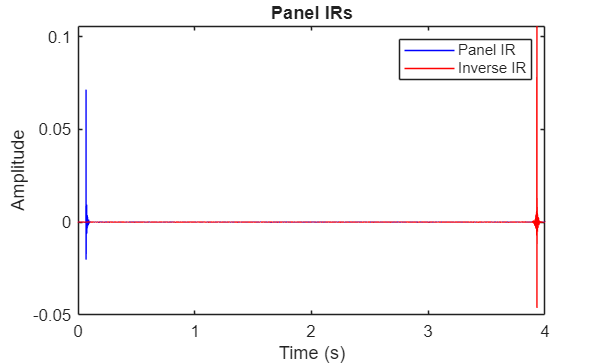

figure
plot(panel.Time, panel_ir, 'b', panel.Time, panel_inverse_ir * 0.2, 'r')
legend('Panel IR', 'Inverse IR')
title('Panel IRs');
xlabel('Time (s)');
ylabel('Amplitude');

y_ir = conv(y_panel, source_ir_norm); % is this supposed to be y_panel or y_source?
y_control = conv(y_panel, panel_inverse_ir); % use y_ir here maybe?

out = [y_control, y_source];
audiowrite("output_clip.wav", out, fs);